# 拟合可以用于缺失**数据补全处理**、用现有数据对未知数据预测等.

## polyfit 一次多项式拟合

clear
clc
x = [0, 3, 5, 7, 9, 11, 12, 13, 14, 15]';
y = [0, 1.2, 1.7, 2.0, 2.1, 2.0, 1.8, 1.2, 1.0, 1.6]';
p = polyfit(x,y,1)

p =     0.0540    0.9791


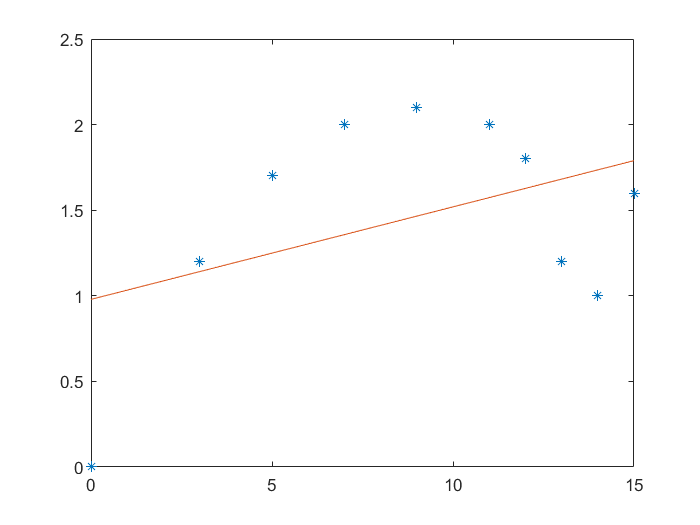

% 因为是线性函数拟合，所以A的前者是k，后者是b，即 y = 0.054x+0.9791
x1 = 0:0.1:15;
y1 = polyval(p,x1);
plot(x,y,'*',x1,y1)

average = mean(x)

average = 8.9000

standard = std(x)

standard = 5.0211

## polyfit 二次多项式拟合

clear
clc
x = [0, 3, 5, 7, 9, 11, 12, 13, 14, 15]';
y = [0, 1.2, 1.7, 2.0, 2.1, 2.0, 1.8, 1.2, 1.0, 1.6]';
p = polyfit(x,y,2)

p =    -0.0249    0.4416    0.0683


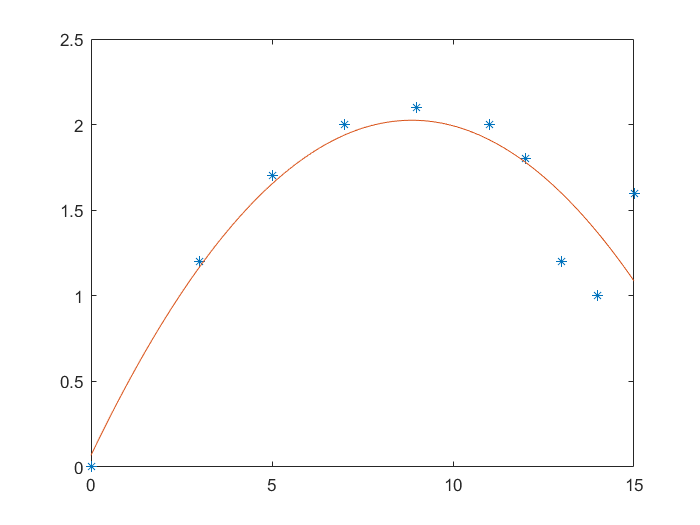

% 因为是抛物线拟合，所以是 y = -0.0249x^2+0.4416x+0.0683
x1 = 0:0.1:15;
y1 = polyval(p,x1);
plot(x,y,'*',x1,y1)

## fittype 非线性自定义拟合

clear
clc
x = [0, 3, 5, 7, 9, 11, 12, 13, 14, 15]';
y = [0, 1.2, 1.7, 2.0, 2.1, 2.0, 1.8, 1.2, 1.0, 1.6]';
p = fittype('a*x+b*sin(x)+c')

p =      General model:
     p(a,b,c,x) = a*x+b*sin(x)+c

f = fit(x,y,p,'StartPoint',[0 0 0])

f =      General model:
     f(x) = a*x+b*sin(x)+c
     Coefficients (with 95% confidence bounds):
       a =     0.06654  (-0.03247, 0.1655)
       b =      -0.327  (-1.042, 0.3882)
       c =      0.8932  (-0.0856, 1.872)

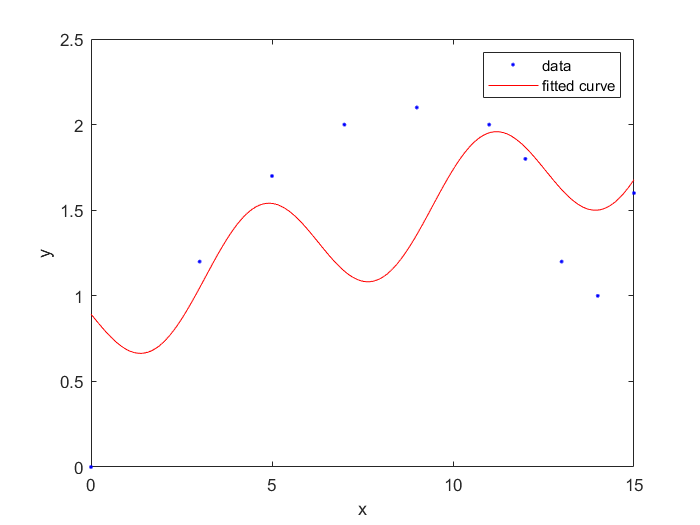

% 参数 abc三个，则初始值就输入三个
plot(f,x,y);

## fittype 非线性三次多项式拟合

clear
clc
x = [0, 3, 5, 7, 9, 11, 12, 13, 14, 15]';
y = [0, 1.2, 1.7, 2.0, 2.1, 2.0, 1.8, 1.2, 1.0, 1.6]';
p = fittype('a*x^3+b*x^2+c*x+d')

p =      General model:
     p(a,b,c,d,x) = a*x^3+b*x^2+c*x+d

f = fit(x,y,p,'StartPoint',[0 0 0 0])

f =      General model:
     f(x) = a*x^3+b*x^2+c*x+d
     Coefficients (with 95% confidence bounds):
       a =    0.001187  (-0.001498, 0.003872)
       b =    -0.05168  (-0.1133, 0.009906)
       c =      0.5939  (0.2052, 0.9825)
       d =    -0.05407  (-0.734, 0.6259)

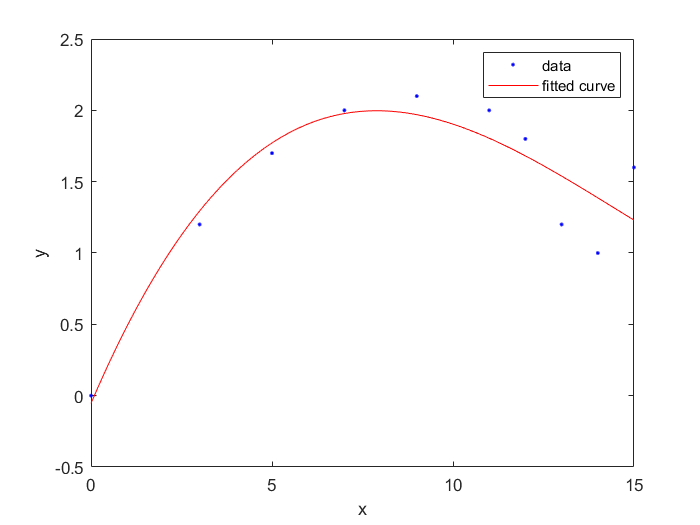

% 参数 abcd四个，则初始值就输入四个
plot(f,x,y);